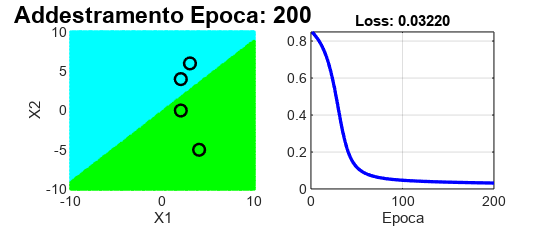

Época 1 :  b = 0.000000  w_1 = 1.000000  w_2 = 0.000000  L = 0.848867
Época 2 :  b = -0.001227  w_1 = 0.997122  w_2 = -0.006297  L = 0.843851
Época 3 :  b = -0.002489  w_1 = 0.994155  w_2 = -0.012777  L = 0.838533
Época 4 :  b = -0.003789  w_1 = 0.991094  w_2 = -0.019451  L = 0.832888
Época 5 :  b = -0.005128  w_1 = 0.987934  w_2 = -0.026327  L = 0.826890
Época 6 :  b = -0.006509  w_1 = 0.984670  w_2 = -0.033416  L = 0.820508
Época 7 :  b = -0.007932  w_1 = 0.981295  w_2 = -0.040730  L = 0.813708
Época 8 :  b = -0.009401  w_1 = 0.977806  w_2 = -0.048281  L = 0.806454
Época 9 :  b = -0.010918  w_1 = 0.974194  w_2 = -0.056082  L = 0.798706
Época 10 :  b = -0.012485  w_1 = 0.970455  w_2 = -0.064145  L = 0.790420
Época 11 :  b = -0.014104  w_1 = 0.966580  w_2 = -0.072485  L = 0.781548
Época 12 :  b = -0.015777  w_1 = 0.962564  w_2 = -0.081117  L = 0.772038
Época 13 :  b = -0.017509  w_1 = 0.958398  w_2 = -0.090054  L = 0.761833
Época 14 :  b = -0.019300  w_1 = 0.954076  w_2 = -0.099314  L 

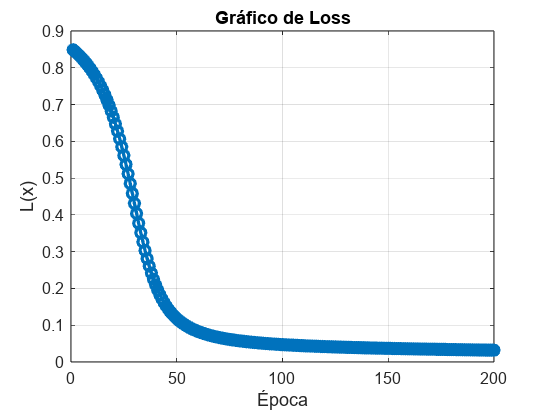

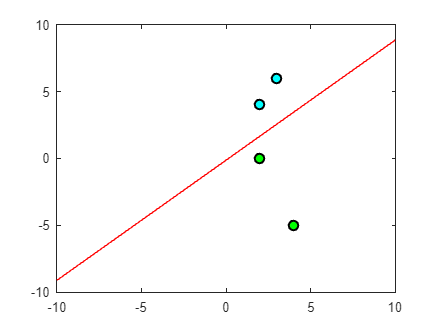

clear all

% --- CONFIGURACIÓN DE DATOS Y PARÁMETROS ---
x = [2 4; 3 6; 2 0; 4 -5];
y = [0 0 1 1];
w = [1, 0];
b = 0;
nu = 0.01;
epocas = 200;

loss_history = nan(1, epocas);

% Configuracion malla
asse_x = -10:0.1:10; 
asse_y = -10:0.1:10;
[X1, X2] = meshgrid(asse_x, asse_y);
puntos_malla = [X1(:), X2(:)];

% Setup GIF
filename = 'training_plane.gif';
if exist(filename, 'file'), delete(filename);end
h = figure('Color', 'w');
set(h, 'Color', 'w', 'Position', [50, 200, 1200, 500]);

% --- BUCLE DE ENTRENAMIENTO ---
for i = 1:epocas
    % Regla del Gradiente
    y_cap = 1./(1 + exp(-(w*x' + b)));
    L = sum((y_cap - y).^2) / 2;
    loss_history(i) = L;
    fprintf('Época %d :  b = %.6f  w_1 = %.6f  w_2 = %.6f  L = %.6f\n', i, b, w(1), w(2), loss_history(i));
    dLw = (((y_cap - y).*y_cap.*(1 - y_cap)))*x;
    dLb = sum((y_cap - y).*y_cap.*(1 - y_cap));
    w_new = w - nu * dLw;
    b_new = b - nu * dLb;
    w = w_new;
    b = b_new;

    % --- VISUALIZACIÓN ---
    clf;
    subplot(1,2,1);
    hold on;
    
    % Cálculo de probabilidades en la malla
    prob_malla = 1./(1 + exp(-(w*puntos_malla' + b)));
    Z = reshape(prob_malla, size(X1));
    
    idx_azul = prob_malla <= 0.5;
    scatter(puntos_malla(idx_azul, 1), puntos_malla(idx_azul, 2), 5, 'c', 'filled');
    idx_verde = prob_malla > 0.5;
    scatter(puntos_malla(idx_verde, 1), puntos_malla(idx_verde, 2), 5, 'g', 'filled');
    
    scatter(x(1:2,1), x(1:2,2), 50, 'c', 'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 1.5);
    scatter(x(3:4,1), x(3:4,2), 50, 'g', 'filled', 'MarkerEdgeColor', 'k', 'LineWidth', 1.5);
    
    title(['Addestramento Epoca: ', num2str(i)], 'FontSize', 14);
    xlabel('X1'); ylabel('X2');

    % GRAFICO LOSS

    subplot(1,2,2);
    plot(1:epocas, loss_history, 'b', 'LineWidth', 2);
    title(['Loss: ', num2str(L, '%.5f')]);
    xlabel('Epoca');
    grid on;
    xlim([0 epocas]); % Mantiene l'asse X costante
    ylim([0 max(loss_history(1), 0.5)]);

    drawnow;

    % --- SALVATAGGIO FRAME GIF ---
    frame = getframe(h);
    im = frame2im(frame);
    [imind, cm] = rgb2ind(im, 256);
    if i == 1
        imwrite(imind, cm, filename, 'gif', 'Loopcount', inf, 'DelayTime', 0.05);
    else
        imwrite(imind, cm, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.05);
    end
end